# Night 7: Eigenfaces

First, load the training data (which contains a 256x256x106 matrix with 106 images that are each 256x256 pixels). Rename the imported varaibles, since the train data, which will be imported later, has the same variable names.

load classdata_train.mat
grayfaces_train = grayfaces;
y_train = y;

Make matrix A, which is the image data, but reshaped so that each image is a 65536 element column vector. 

A1 = reshape(grayfaces, 65536, 106);
size(A1)

ans =        65536         106


clear grayfaces

Display average QEA student for fun

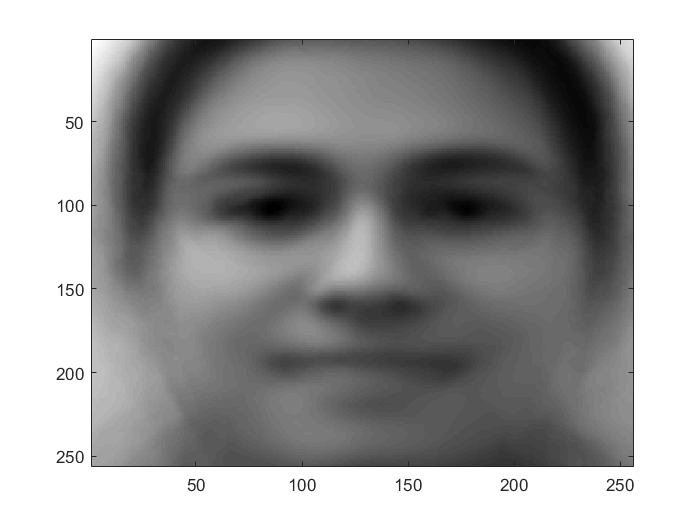

avg_QEA = (sum(A1,2)./106);
imagesc(reshape(avg_QEA, 256, 256)); colormap('gray')

Normalize matrix A by making a matrix by repeating a column vector that contains the sum of each row, and subtracting the resulting matrix from A. 

A = A1 - repmat((sum(A1,2)./106),1,106);
clear A1

Find decomposition (basically Eigenvectors and eigenvalues) of covariance matrix

U is a matrix of the eigenvalues (106x106)

S is variance in direction of egienvector s^2 are eigenvalues (106x106)

[U,S,V] = svd(transpose(A)*A);

Find U with equation ui = A*vi

 U1 (65536x106) 

U1 = (A*V);
clear U
clear S
clear V

Determine which eigenvectors from U are most important (which have the largest eigenvalues, but the first few have to do with lighting, so dispose of those), and throw out all the unnecessary eigenvectors and values. 

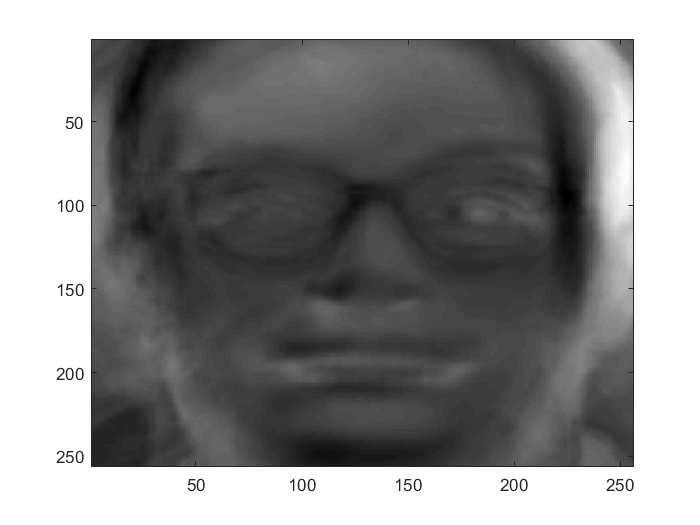

U20 = U1(:,4:18); % extract 20 entries
imagesc(reshape(U20(:,1), 256, 256)); colormap('gray') %display an eigenface

Then find out how much of each eigenvector is used to represent each face (find weights).

Weights = Transpose(U)*Image

Wtrain = transpose(U20)*A;

## When given a new face, find the weights and compare those to all existing weights 

Load test version of grayfaces and y, and assign to their own variables

load classdata_test.mat
grayfaces_test = grayfaces;
y_test = y;

Reshape and normalize in the same way as with the training data

A1 = reshape(grayfaces, 65536, 318);
size(A1)

ans =        65536         318


Atest = A1 - repmat((sum(A1,2)./318),1,318);
clear A1
Wtest = transpose(U20)*Atest;

Select random image from testing set, run random image through a for loop that compares every weight vector in the train matrix with the selected test image's weights, finds the minimum difference between the test image and the train image (the closest image between the test and train images). 

Display images, check if asociated names are the same, and return true if so, and false if not

n = randi([1 318],1,1)

n = 174

Wn = Wtest(:,n);
WL = zeros(1,106);
for i = 1:106
   WL(i) = WL(i)+ sum(abs(Wtrain(:,i)-Wn));
end
[M,I] = min(WL)

M = 5.4754e+07

I = 58

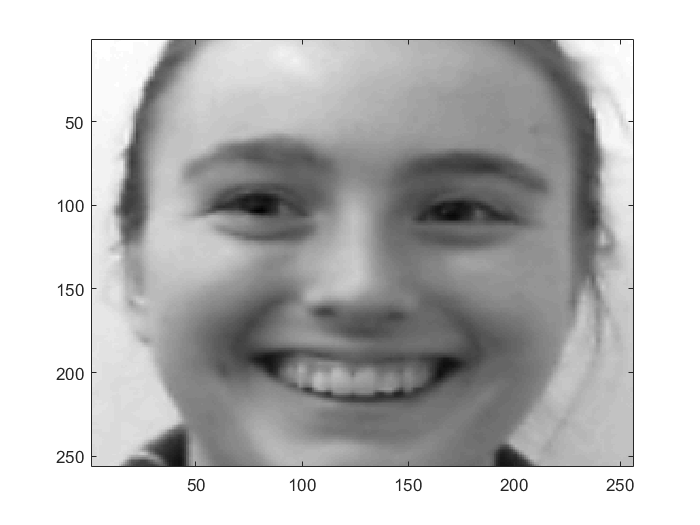


imagesc(grayfaces_train(:,:,I)); colormap('gray')

y_train.name(I)

ans = 1×1 cell array
    {'katie_goldstein'}


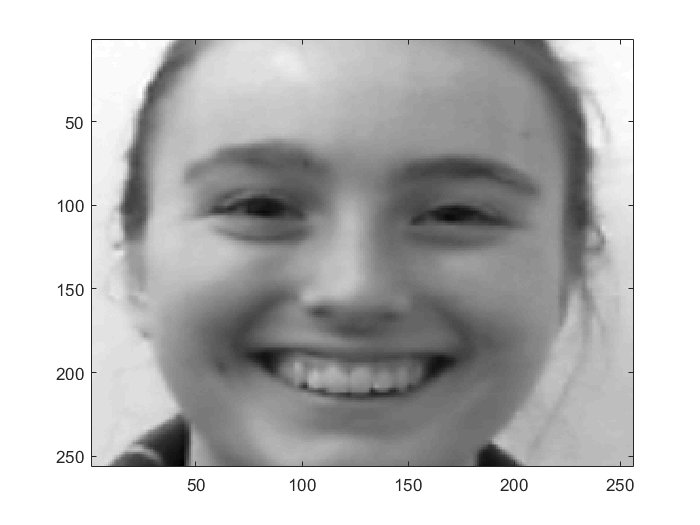

imagesc(grayfaces_test(:,:,n)); colormap('gray')

y_test.name(n)

ans = 1×1 cell array
    {'katie_goldstein'}



if strcmp(y_train.name(I), y_test.name(n))
    disp("true")
else
    disp("false")
end

true


## Run for all faces in test set and determine accuracy

Change number of eigenvectors and run again

U20 = U1(:,4:18); %change which and how many eigenvectors are used
Wtrain = transpose(U20)*A;
Wtest = transpose(U20)*Atest;

num_true = 0;
num_false = 0;
tagged_false = 0;
tagged_false_list = [];
false_list = [];
for n = 1:318
    Wn = Wtest(:,n);
    WL = zeros(1,106);
    for i = 1:106
       WL(i) = WL(i) + sum(abs(Wtrain(:,i)-Wn));
    end
    [M,I] = min(WL);
    if sum(abs(Wtrain(:,i)-Wn)) > 350000000
%       disp("Probably incorrect")
       tagged_false = tagged_false + 1;
       tagged_false_list = [tagged_false_list,n];
    end
    if strcmp(y_train.name(I), y_test.name(n))
        num_true = num_true+1;
        %disp(sum(WL))
    else
        num_false = num_false+1;
        in = [I,n];
        false_list = [false_list, n];
    end
end

disp("Number correct: "+ num_true)

Number correct: 298


disp("Number incorrect: "+ num_false)

Number incorrect: 20


disp("Percentage correct: "+num_true/(num_false+num_true)*100)

Percentage correct: 93.7107


disp("Tagged False: "+tagged_false)

Tagged False: 25


false_list = sort(false_list)

false_list =     11    12    27    28    50   103   104   105   108   154   155   156   172   175   177   182   244   245   254   311


for j = (size_false_list(:,2))

    imagesc(grayfaces_train(:,:,false_list(j-1))); colormap('gray')

    y_train.name(j)

    imagesc(grayfaces_test(:,:,n)); colormap('gray')

    y_test.name(n)

end

## Data:

With 20 Eigenvectors: (experimenting with how many to cut off in the beginning. Ideal seems to be starting at 4)

3:22 -> 87.7% 

4:23 -> 92.5%

5:24 -> 90.9%

It takes 5 eigenvectors to get the accuracy above 50% when starting at the 4th eigenvector

All of this data was taken starting at the 4th Eigenvector (one with 4th highest asociated eigenvalue):

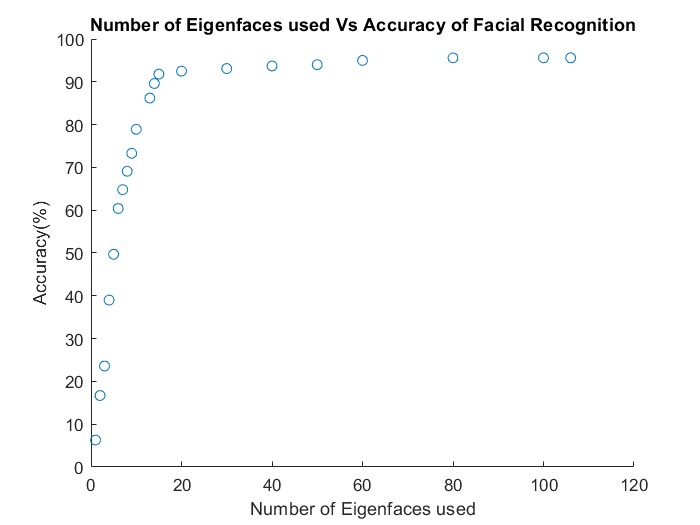

D = [1 6.3
2 16.7
3 23.6
4 39.0
5 49.7
6 60.4
7 64.8
8 69.1
9 73.3
10 78.9
13 86.2
14 89.6 
15 91.8
20 92.5
30 93.1
40 93.7
50 94.0
60 95.0
80 95.6
100 95.6
106 95.6];
scatter(D(:,1),D(:,2))
title("Number of Eigenfaces used Vs Accuracy of Facial Recognition")
xlabel("Number of Eigenfaces used")
ylabel("Accuracy(%)")

It seems like the ideal number of eigenvectors to use in order to have get the most accuracy without using too much processing power is 15.

## Run for students not in the training set

load classdata_full.mat

Wtrain = transpose(U20)*A;
Wtest = transpose(U20)*Atest;

num_true = 0;
num_false = 0;
tagged_false = 0;
false_list = [];
tagged_false_list = [];
for n = 1:318
    Wn = Wtest(:,n);
    WL = zeros(1,106);
    for i = 1:106
       WL(i) = WL(i) + sum(abs(Wtrain(:,i)-Wn));
    end
    [M,I] = min(WL);
    if sum(abs(Wtrain(:,i)-Wn)) > 340000000
       disp("Probably incorrect")
       tagged_false = tagged_false + 1;
       tagged_false_list = [tagged_false_list,I,n]
    end
    if strcmp(y_train.name(I), y_test.name(n))
        num_true = num_true+1;
        %disp(sum(WL))
    else
        num_false = num_false+1;
        false_list = [false_list, I, n];
    end
end

Probably incorrect


tagged_false_list =     21    61


Probably incorrect


tagged_false_list =     21    61    22    62


Probably incorrect


tagged_false_list =     21    61    22    62    22    63


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


Probably incorrect


tagged_false_list =     21    61    22    62    22    63    22    64    22    65    22    66    31    91    31    92    31    93    32    96    33    97    33    98    33    99    43   127    43   128    43   129    44   130    44   131    44   132    47   140    47   141    33   156    73   217    73   218    73   219


disp("Number correct: "+ num_true)

Number correct: 298


disp("Number incorrect: "+ num_false)

Number incorrect: 20


disp("Percentage correct: "+num_true/(num_false+num_true)*100)

Percentage correct: 93.7107


%disp("False List: "+false_list)
disp("Tagged False: "+tagged_false)

Tagged False: 33


size_false_list = size(false_list);